# AAE340 HW#4

## <3c>

numerically integrate 


$$\overset{\cdot \cdot }{r} -r{\left(\theta^{\cdot } \right)}^2 =\frac{-\mu \;}{r^2 }\;$$



$$r\;\theta^{\cdot \cdot } \;+2\overset{\cdot }{r} \;\theta^{\cdot } \;=0$$


## Solving ODE45

a = 24458540.03;  % Semimajor axis
myu = 0.3986*10^15;  % GM constant
t_f = pi*sqrt(a^3/myu);  % The upper limit of time -> is the half period of the elliptical transfer orbit
t_span = 0:t_f;
x0 = [6676000, 0, 0, 1.521060181*10^(-3)];  % Defining the initial conditions
[t, x] = ode45(@(t,x) dfcn(t,x), t_span, x0);
r = x(:,1);  % Assigning the numerical values of r to a variable 
r_dot = x(:,2);  % Assigning the numerical values of r dot to a variable
theta = x(:,3);  % Assigning the numerical values of theta to a variable
theta_dot = x(:,4);  % Assigning the numerical values of theta dot to a variable

## Plotting 

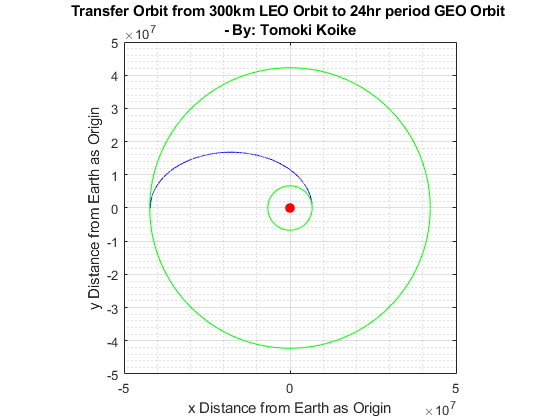

% Converting cylindrical coordinates to Cartesian
x_coord = r.*cos(theta);  
y_coord = r.*sin(theta);

% The LEO orbit 
phi = 0:0.01:2*pi;
x_leo = 6676000.*cos(phi);
y_leo = 6676000.*sin(phi);

% The GEO orbit 
x_geo = 42241080.07.*cos(phi);
y_geo = 42241080.07.*sin(phi);

figure(1);
plot(x_coord, y_coord, '-b')
xlabel('x Distance from Earth as Origin')
ylabel('y Distance from Earth as Origin')
title({'Transfer Orbit from 300km LEO Orbit to 24hr period GEO Orbit ',['-' ...
    ' By: Tomoki Koike']})
grid on
grid minor
box on
hold on 
plot(0,0,'.r', 'MarkerSize',25)  % Indicating Earth 
plot(x_leo, y_leo, '-g')  % Indicating LEO orbit
plot(x_geo, y_geo, '-g')  % Indicating GEO orbit
hold off
axis square

## <3d>

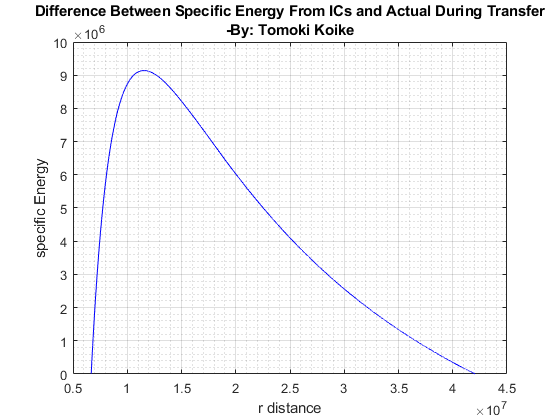

e_num = 0.5.*r.^2.*theta_dot.^2 - myu./r;  % Numerical
e_th = 0.5.*(r.^2.*theta_dot.^2 + r_dot.^2) - myu./r;  % Theoretical 

e_diff = e_th - e_num;  % Difference of specific energy 

% Plotting 
figure(2)
plot(r, e_diff, '-b')
xlabel('r distance')
ylabel('specific Energy')
title({'Difference Between Specific Energy From ICs and Actual During Transfer',['-' ...
    'By: Tomoki Koike']})
grid on
grid minor
box on

## ANALYSIS

This plot shows that the actual specific energy which includes the r_dot sqaured term diverges the specific energy dramatically when it is closer to the perigee. Whereas, when it approaches the apogee the difference between the actual and IC-computed become close to each other. The linear velocity becomes larger when it is closer to the apogee. 

function dxdt = dfcn(t,x)
myu = 0.3986*10^15;
dxdt = zeros(4,1);   % Defining a zero vector to store the dxdt terms 
dxdt(1) = x(2);  % Derivative of x1 = x2
dxdt(2) = x(1)*x(4)^2 - myu/x(1)^2;  % Derivative of x2 
dxdt(3) = x(4);  % Derivative of x3 
dxdt(4) = -2*x(2)*x(4)/x(1);  % Derivative of x4
end  